# ShowGraph Demo

This LiveScript show the different options of the ShowGraph function

### Read the model file

filename = "C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
model = ThermoeconomicModel(filename,'Debug',false);

### Show the available tables of the model

ListResultTables(model);


Tables Directory

 Table        Description                          Results                   Graph  
——————————————————————————————————————————————————————————————————————————————————————
 flows        Flows Definition Table               Productive Structure      false  
 processes    Processes Definition Table           Productive Structure      false  
 streams      Productive Groups Definition Table   Productive Structure      false  
 eflows       Flows Exergy Table                   Exergy Analysis           false  
 eprocesses   Processes Exergy Table               Exergy Analysis           false  
 estreams     Productive Groups Exergy Table       Exergy Analysis           false  
 tfp          FP Table                             Exergy Analysis           true   
 dfcost       Flows Exergy Cost                    Thermoeconomic Analysis   false  
 dcost        Process Exergy Cost                  Thermoeconomic Analysis   false  
 ducost       Process Unit Exergy Cost      

### Select and show a graph table of the model

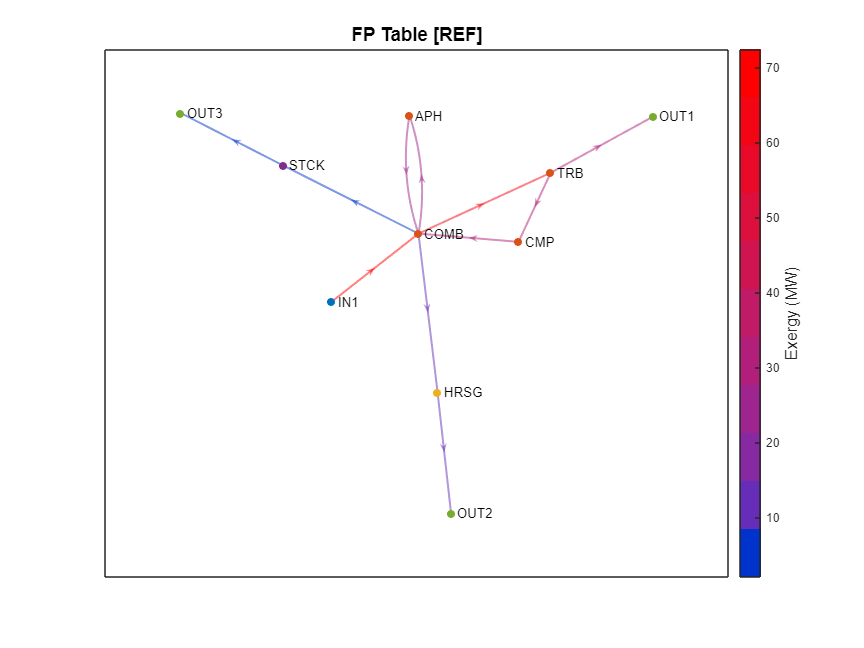

graphs=string(model.ListOfGraphs);
ShowGraph(model,'Graph',char(graphs(1)));

### **Thermoeconomic Diagnosis**

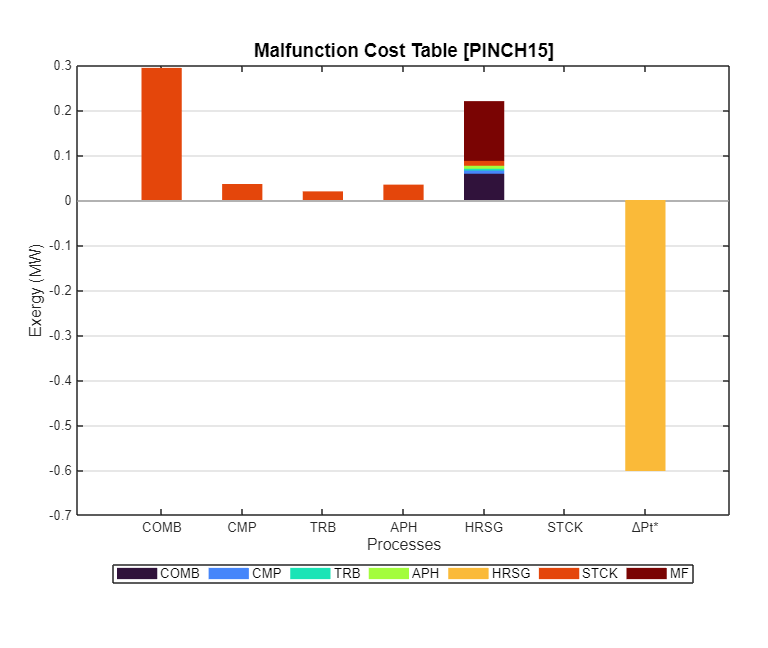

model.setDiagnosisMethod('WASTE_INTERNAL');
States=string(model.StateNames);
state=char(States(6));
model.setState(state);
res = model.thermoeconomicDiagnosis;
ShowGraph(res,'Graph','mfc');

Use` 'ShowOutput' `option for thermoeconomic diagnosis graphs

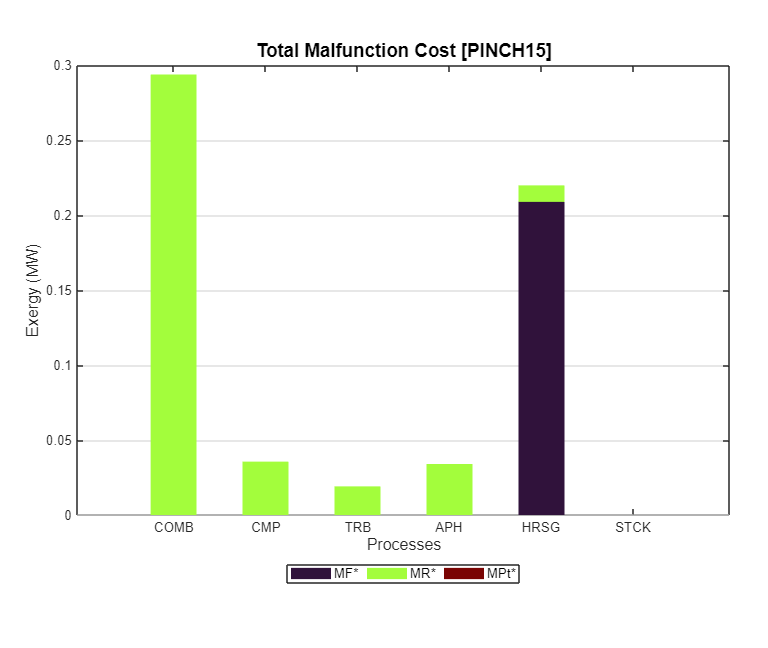

ShowGraph(res,'Graph',cType.Tables.TOTAL_MALFUNCTION_COST,'ShowOutput',false);

res.summaryDiagnosis;

Fuel Impact:          0.0000 (MW)
Technical Saving:     0.6021 (MW)



### **Summary Results**

Show the default summary graph

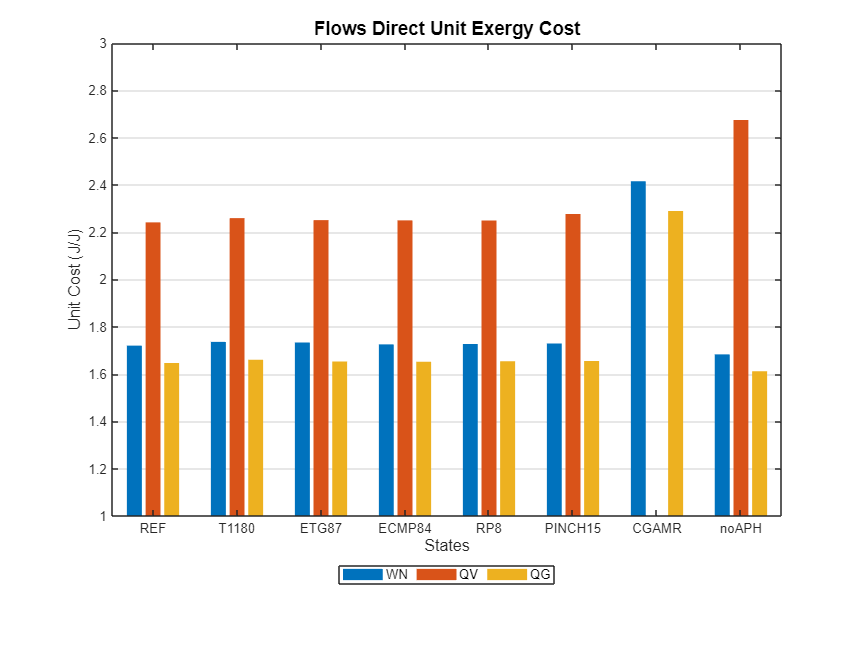

model.setSummary('STATES');
res=model.summaryResults;
ShowGraph(res);

Use the option `'Variables' `in Summary Results to select flows. By default all the `output flows` are shown.

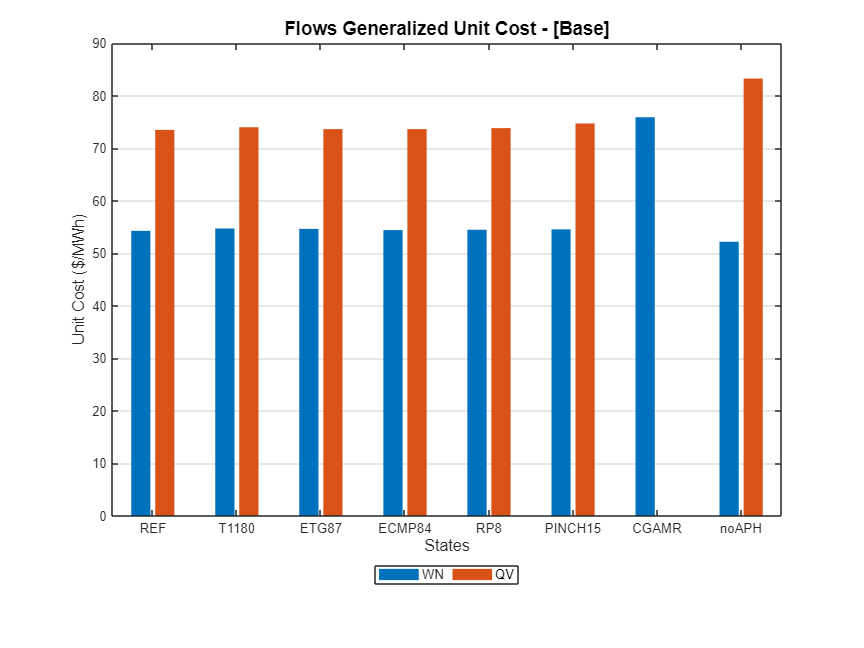

vars={'QV','WN'};
model.setCostTables('ALL')
ShowGraph(res,'Graph',cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST,'Variables',vars);

### **Waste Allocation**

Use the option `'WasteFlow' `to select the waste flow to show. By default `ActiveWaste` is used.

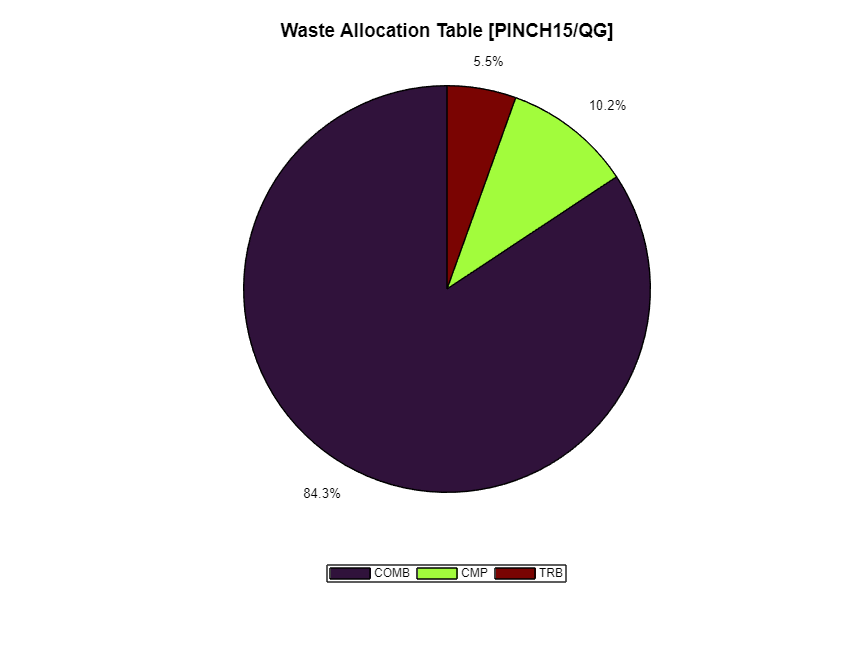

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

Use the option `'PieChart' to false `to show all waste flows allocations in a horizontal bar graph.

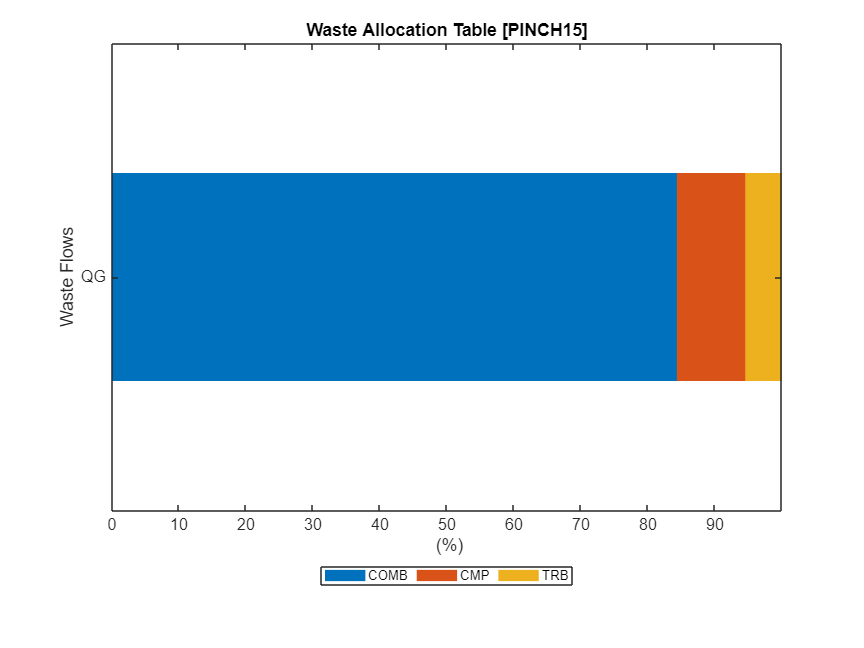

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION,'PieChart',false);

### Waste Recycling

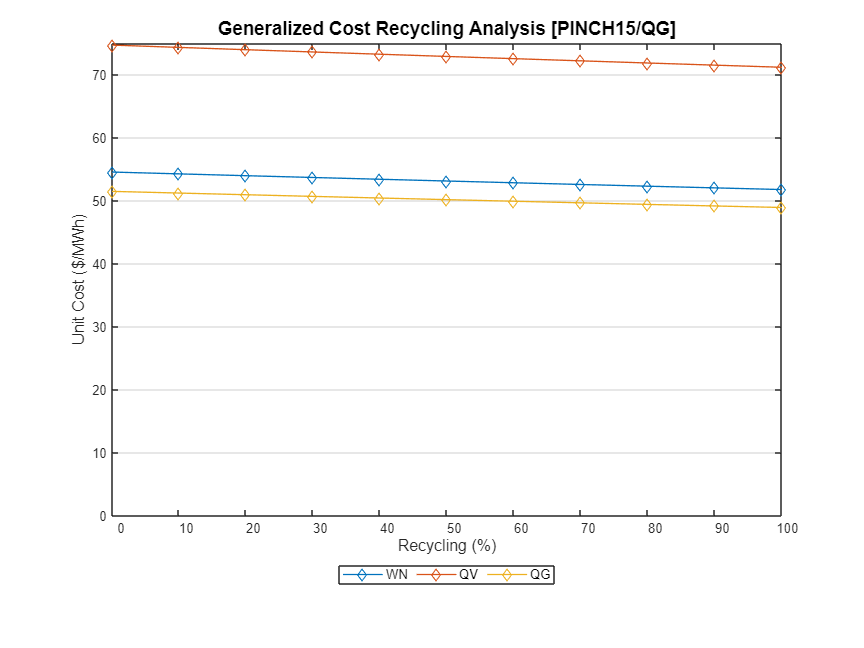

model.setRecycling(true);
ShowGraph(model,'Graph',cType.Tables.WASTE_RECYCLING_GENERAL);

### Additional Help Information

help ShowGraph

 ShowGraph - Display the graph associated with a results table.
 	Depending on the graph, additional options could be used.
 
    Syntax 
      ShowGraph(arg,Name,Value)
  
    Input Argument
      arg - cResultSet object
 
    Name-Value Arguments
      Graph: Name of the table
        char array
      ShowOutput: Show Output variation.Use for Diagnosis tables. 
        false | true (default)
      PieChart: Use Pie Chart graph for Waste Allocation
        false | true (default) 
      BarGraph: Use Bar Graph for Summary results
        false | true (default)
      Variables: Variables used in Summary results. 
        cell array
 
    Example
      Show Graph Demo
 
    See also cGraphResults, cResultSet

